# Modelo *E.coli*

#### Autor: H. Scott Hinton, Utah State University

#### **Editado y traducido**: German Preciat, Universidad de Guadalajara

#### Universidad de Guadalajara

#### **Carrera: Ing. Biomédica**

#### **Materia: Ingeniería Metabólica**

#### Contacto: german.preciat@academicos.udg.mx

## INTRODUCCIÓN

El propósito de este tutorial es mostrarle a un principiante cómo se puede usar COBRA Toolbox para explorar la fisiología de una célula. Para ilustrar las capacidades de COBRA Toolbox [1, 2], este tutorial se centrará en explorar los atributos del modelo central de *E.coli* que fue desarrollado por Orth, Fleming y Palsson [3] y está incluido en la instalación estándar de COBRA Toolbox. Este tutorial no se centrará en la fisiología detallada representada por el modelo central, ya que se ha publicado en detalle en otro lugar [3], sino que se centrará en cómo utilizar COBRA Toolbox para explorar el núcleo de E.coli o cualquier otro modelo basado en COBRA. .

Este tutorial incluirá discusiones pragmáticas de los siguientes temas:

- Las limitaciones del modelado basado en restricciones.

- Componentes básicos de un modelo COBRA que incluyen: A) genes, B) reacciones, C) metabolitos, D) asociaciones gen-proteína-reacción, E) restricciones y F) funciones objetivas.

- Una descripción general del análisis de balance de flujo (FBA).

- Los subsistemas del modelo central de* E.coli* que incluyen secciones sobre A) gestión de la energía de la célula, B) vía de la glucólisis, C) vía de las pentosas fosfato, D) ciclo del ácido tricarbonoxilico, E) ciclo del glucoxilato, gluconeogénesis y reacciones anapleuróticas, F) fermentación, y G) el metabolismo del nitrógeno.

## MATERIALES

Este tutorial se basa en la caja de herramientas de análisis y reconstrucción basada en restricciones (COBRA Toolbox) [2,3] que se encuentra en constante en desarrollo. Para usar este tutorial, necesitará la versión 2018b o más reciente de Matlab ([https://www.mathworks.com/](https://www.mathworks.com/)) y el software de COBRA Toolbox se puede descargar desde [https://github.com/opencobra/cobratoolbox](https://github.com/opencobra/cobratoolbox). Las instrucciones de instalación y los consejos para la solución de problemas también están disponibles en este sitio web.

## **CONFIGURACIÓN DEL EQUIPO**

Para utilizar COBRA Toolbox, primero debe inicializar el entorno de Matlab para incluir todas las funciones de COBRA Toolbox. Antes de inicializar COBRA Toolbox, inicie Matlab y muévase al directorio de Matlab que desea que sea su directorio de trabajo. La inicialización de COBRA Toolbox se logra con la función "`initCobraToolbox`" como se muestra a continuación. *[Tiempo: < Minuto]*

initCobraToolbox(false) % false, as we don't want to update
% change to the directory of the tutorial
cd(fileparts(which('tutorial_ecoliCoreModel_part1.mlx')));

**SOLUCIÓN DE PROBLEMAS**

Uno de los mayores problemas que enfrentan los usuarios de este tutorial es que no han configurado correctamente el "solver" antes de comenzar el tutorial. Esto es necesario para las optimizaciones de red requeridas por este tutorial. Esto se puede hacer seleccionando el solucionador apropiado para la máquina que está utilizando eliminando el signo "%" (comentario) solo para el solucionador deseado. *[Tiempo: segundos]*

% changeCobraSolver('glpk', 'all');

## PROCEDIMIENTO

## 1. Modelado basado en restricciones

Tanto las reconstrucciones de redes metabólicas a escala del genoma [4] como el modelado basado en restricciones [5,6,7] se pueden usar para modelar fenotipos de estado estacionario durante la fase de crecimiento exponencial. Esto puede ser útil para explorar y comprender las capacidades de cada fenotipo. También se puede utilizar para identificar y modificar vías celulares para favorecer fenotipos productores de bioproductos específicos. Es importante entender que la mayoría de los modelos basados en restricciones no pueden

- Modelar transiciones entre fenotipos,

- Incluir los genes necesarios para la fase estacionaria (proteasas, etc.),

- Incluyen las rutas completas de transcripción y traducción.

Estos modelos basados en restricciones se basan en una función de biomasa que representa la carga metabólica promedio requerida durante el crecimiento celular exponencial. Representa los porcentajes medios de las partes componentes (aminoácidos, nucleótidos, energía, etc.) que se incluyen en 1 g de peso seco por hora de biomasa celular.

Mediante el uso de reconstrucciones de redes metabólicas a escala genómica, el análisis de equilibrio de flujo (FBA) [8] se puede utilizar para calcular el flujo de metabolitos a través de una red metabólica (unidad de flujo = $\textrm{mol}/\textrm{gDW}/\textrm{hr}$). Esta capacidad hace posible predecir la tasa de crecimiento de un organismo y/o la tasa de producción de un metabolito dado. ¡Es importante que se entienda que FBA tiene limitaciones! No utiliza parámetros cinéticos, por lo que no puede predecir las concentraciones de metabolitos. Además, solo es capaz de determinar flujos en estado estacionario. Finalmente, la FBA tradicional no tiene en cuenta los efectos reguladores, como la activación de enzimas por las proteínas quinasas o la regulación de la expresión génica. Por lo tanto, sus predicciones pueden no ser siempre precisas.

En este tutorial, mostraremos algunos ejemplos sencillos utilizando la toolbox de Matlab COnstraint-Based Reconstruction and Analysis (COBRA Toolbox) [4,5], un paquete de software que funciona en el entorno de programación Matlab ([https://www.mathworks.com/](https://www.mathworks.com/)). . Como verá, COBRA Toolbox permite a los usuarios explorar el funcionamiento de un modelo de celda con solo unas pocas líneas de código. Estos resultados se pueden usar para predecir el comportamiento celular que, en algunos casos, se ha verificado experimentalmente.

## **2. Componentes básicos de un modelo COBRA**

COBRA Toolbox se basa en reconstrucciones de redes metabólicas que son bases de datos estructuradas bioquímica, genética y genómicamente (BiGG) compuestas de reacciones bioquímicas y metabolitos [9,10]. Almacenan información metabólica del organismo celular, como la estequiometría de la reacción, la reversibilidad de la reacción y las relaciones entre genes, reacciones y proteínas (enzimas). Aunque muchos organismos tienen redes metabólicas centrales similares, puede haber diferencias significativas incluso entre dos organismos estrechamente relacionados, por lo tanto, las reconstrucciones de redes metabólicas son específicas del organismo [4]. Un modelo simplificado de *E.coli*, denominado modelo central de *E.coli*, es un gran modelo para explorar las herramientas de análisis y exploración disponibles a través de la COBRA Toolbox, que es el objetivo de este tutorial. El mapa metabólico del modelo central de *E.coli* se muestra a continuación en la Figura 1. En esta figura, las letras más grandes en este mapa (Glyc, PPP, etc.) se refieren a los principales subsistemas incluidos en este modelo simple que incluye; (OxP) fosforilación oxidativa o gestión de la energía de la célula, vía de la glucólisis (Glyc), vía de la pentosa fosfato (PPP), ciclo del ácido tricarboxílico (TCA), ciclo del glucoxilato (Ana), gluconeogénesis y reacciones anapleuróticas, fermentación (Ferm) y (N) metabolismo del nitrógeno. Todos estos subsistemas se analizarán con más detalle más adelante en este tutorial.

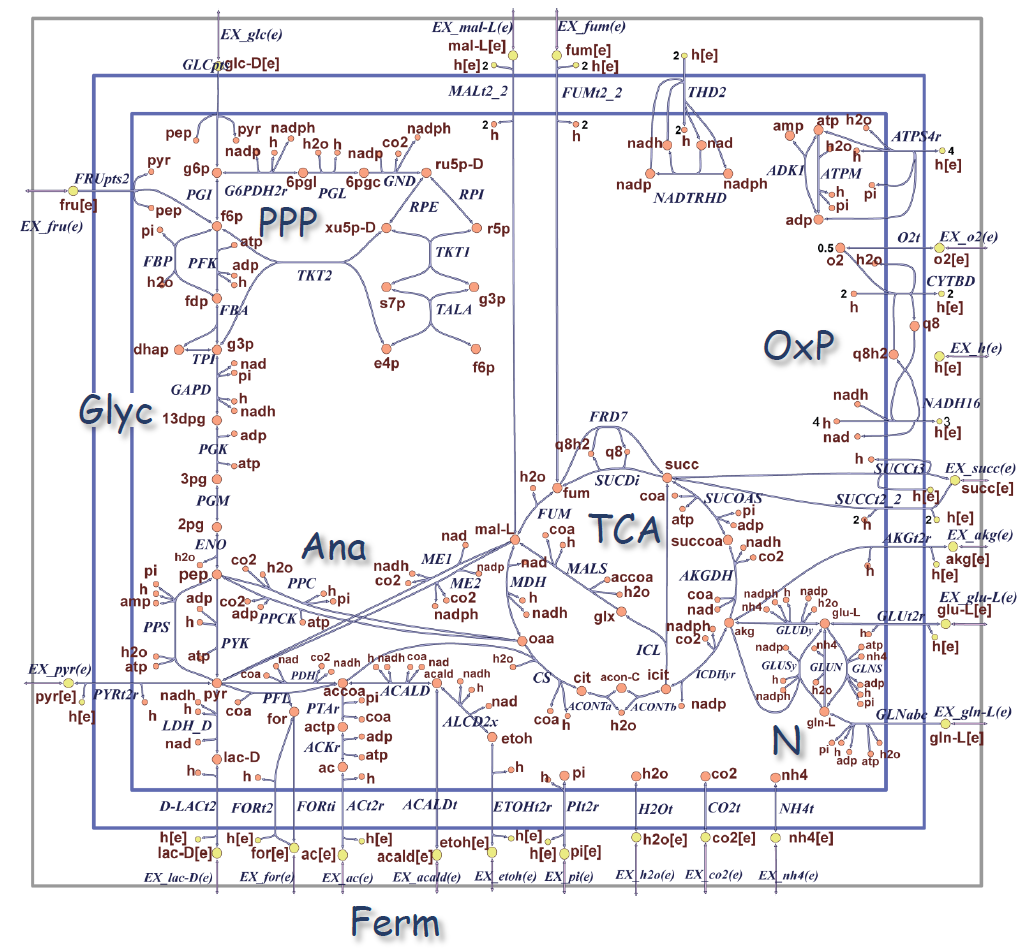

**Figura 1**. Mapa metabólico del modelo central de *E.coli* [3].

Una reconstrucción metabólica consta de una colección de genes, reacciones que representan proteínas (enzimas), metabolitos, una matriz estequiométrica que define la relación entre las reacciones y los metabolitos, restricciones de reacción y una función de biomasa. Los genes en el modelo están representados por el nombre del gen y el locus genómico. Los metabolitos se representan con caracteres en minúsculas y, por lo general, tienen un sufijo que representa el compartimento en el que operan. Para el modelo central simplificado de *E.coli*, solo se representan dos compartimentos; metabolitos citosólicos con el sufijo "`[c]`" y metabolitos extracelulares con el sufijo "`[e]`". Para simplificar este modelo, el modelo central de *E.coli* no distingue entre el espacio periplásmico y el medio extracelular. La representación de metabolitos del modelo COBRA incluye una abreviatura, el nombre oficial, la fórmula química y la carga del metabolito.

Las reacciones en los modelos COBRA corresponden a las enzimas en una celda y se representan mediante abreviaturas en mayúsculas, un nombre oficial y una fórmula estequiométrica. Los sufijos utilizados en las abreviaturas de reacción incluyen; '`i`' (irreversible), '`r`' (reversible), '`abc`' (transportador de cassette de enlace ATP) y '`t`' (transporte). La mayoría de las reacciones utilizadas en el modelo llevan el nombre de las enzimas que las catalizan. Como ejemplo, `ENO` representa la enzima "enolasa" e incluye la fórmula "`2pg[c] <=> h2o[c] + pep[c]`". Un tipo especial de reacción que se encuentra en los modelos COBRA son las reacciones de intercambio que tienen la forma de "`EX_xxx(e)`" y se utilizan para secretar/captar metabolitos hacia/desde el espacio extracelular. Como ejemplo, la reacción de intercambio de glucosa es "`EX_glc(e)`".

Los modelos COBRA también incluyen reglas booleanas para cada reacción que describen la relación gen-reacción. Por ejemplo, 'gen1 y gen2' indican que los dos productos génicos son parte de una enzima, mientras que 'gen1 o gen2' indican que los dos productos génicos son isoenzimas que catalizan la misma reacción. Las asociaciones gen-proteína-reacción (GPRA) para en la Figura 2 se muestran algunas reacciones. Cada GPRA se compone de un locus de gen, un péptido traducido (ARNm) y proteínas funcionales que trabajan juntas para hacer una sola reacción (enzima). En la parte superior de cada GPRA se destaca una parte del contexto genómico. Los genes en esta figura están designados por su nombre de locus y representados por cuadros de color azul claro. Los péptidos traducidos están representados por recuadros morados, las proteínas funcionales están representadas por óvalos rojos, mientras que las reacciones están etiquetadas con recuadros azul oscuro. Como se puede ver en la figura, las isoenzimas incluyen dos proteínas diferentes que están conectadas a la misma reacción. Para el caso de proteínas con múltiples subunidades peptídicas, los péptidos están conectados con un signo '&' sobre la proteína. Para complejos de muchas proteínas funcionales, las proteínas también están conectadas con un signo '`&`' encima de la reacción. Ciertos genes que son responsables de la creación de una reacción dada, como pykF y pykA, pueden ser codificados por genes en operones que están muy separados en el genoma. En esta figura, los operones están representados por rectángulos sombreados alrededor de uno o más genes. Los genes están representados por rectángulos con un lado apuntado para indicar la dirección de la hebra sentido. Otros operones pueden contener múltiples genes que codifican subunidades de proteínas en proteínas más grandes. Como ejemplo, el mismo operón sdhCDAB-sucABCD que codifica las proteínas SUCDi también codifica dos proteínas del complejo enzimático 2-oxoglutarato deshidrogenasa, AKGDH.

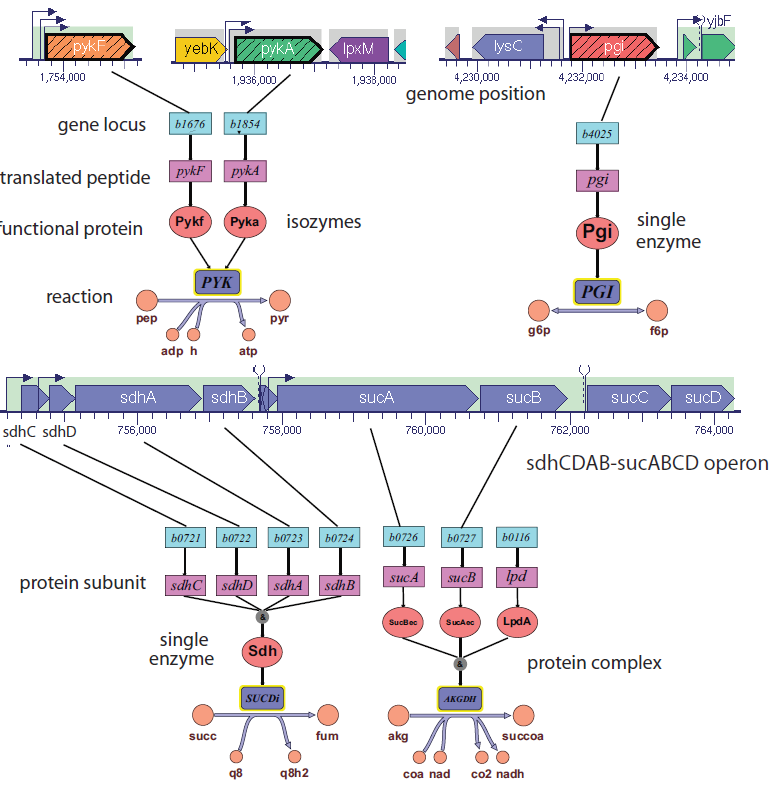

**Figura 2.** Ejemplos de asociaciones gen-proteína-reacción del modelo central de *E.coli* [3].

Ahora comencemos a usar COBRA Toolbox para comenzar a explorar el modelo central de *E.coli*. Lo primero que hay que hacer es cargar el modelo en el entorno de trabajo de Matlab. Esto se puede lograr cargando la versión de Matlab del modelo (.mat) en Matlab. Este modelo está disponible en el software de COBRA Toolbox descargado. *[Tiempo: segundos]*

global CBTDIR
model = readCbModel([CBTDIR filesep 'test' filesep 'models' filesep 'mat' filesep 'ecoli_core_model.mat']);
e_coli_core = model; % Guardar el modelo original para su uso posterior

Después de cargar el modelo central de *E.coli* en Matlab, debería poder mirar el lugar de trabajo de MATLAB y ver que el modelo está cargado como se muestra en la Figura 3.

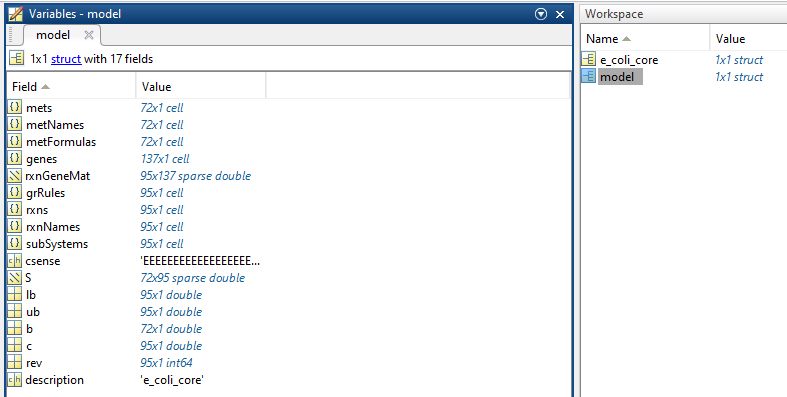

**Figura 3.** Espacio de trabajo de Matlab después de cargar el modelo central de *E.coli* en Matlab.

Quizás la forma más fácil de acceder a toda la información del modelo COBRA es imprimir una hoja de cálculo que contenga toda la información almacenada en el modelo. Esto se puede lograr usando la función "`writeCbModel`". *[Tiempo: segundos]*

outmodel = writeCbModel(model)

Esta función escribirá el modelo en una hoja de cálculo de Excel llamada "core_model.xls" y le permitirá explorar todos los detalles asociados con las reacciones y los metabolitos del modelo. Esto se ilustra en la Figura 4. También puede obtener información específica sobre genes, reacciones, metabolitos y GPRA utilizando las funciones de COBRA Toolbox. Esto se mostrará más adelante en este tutorial.

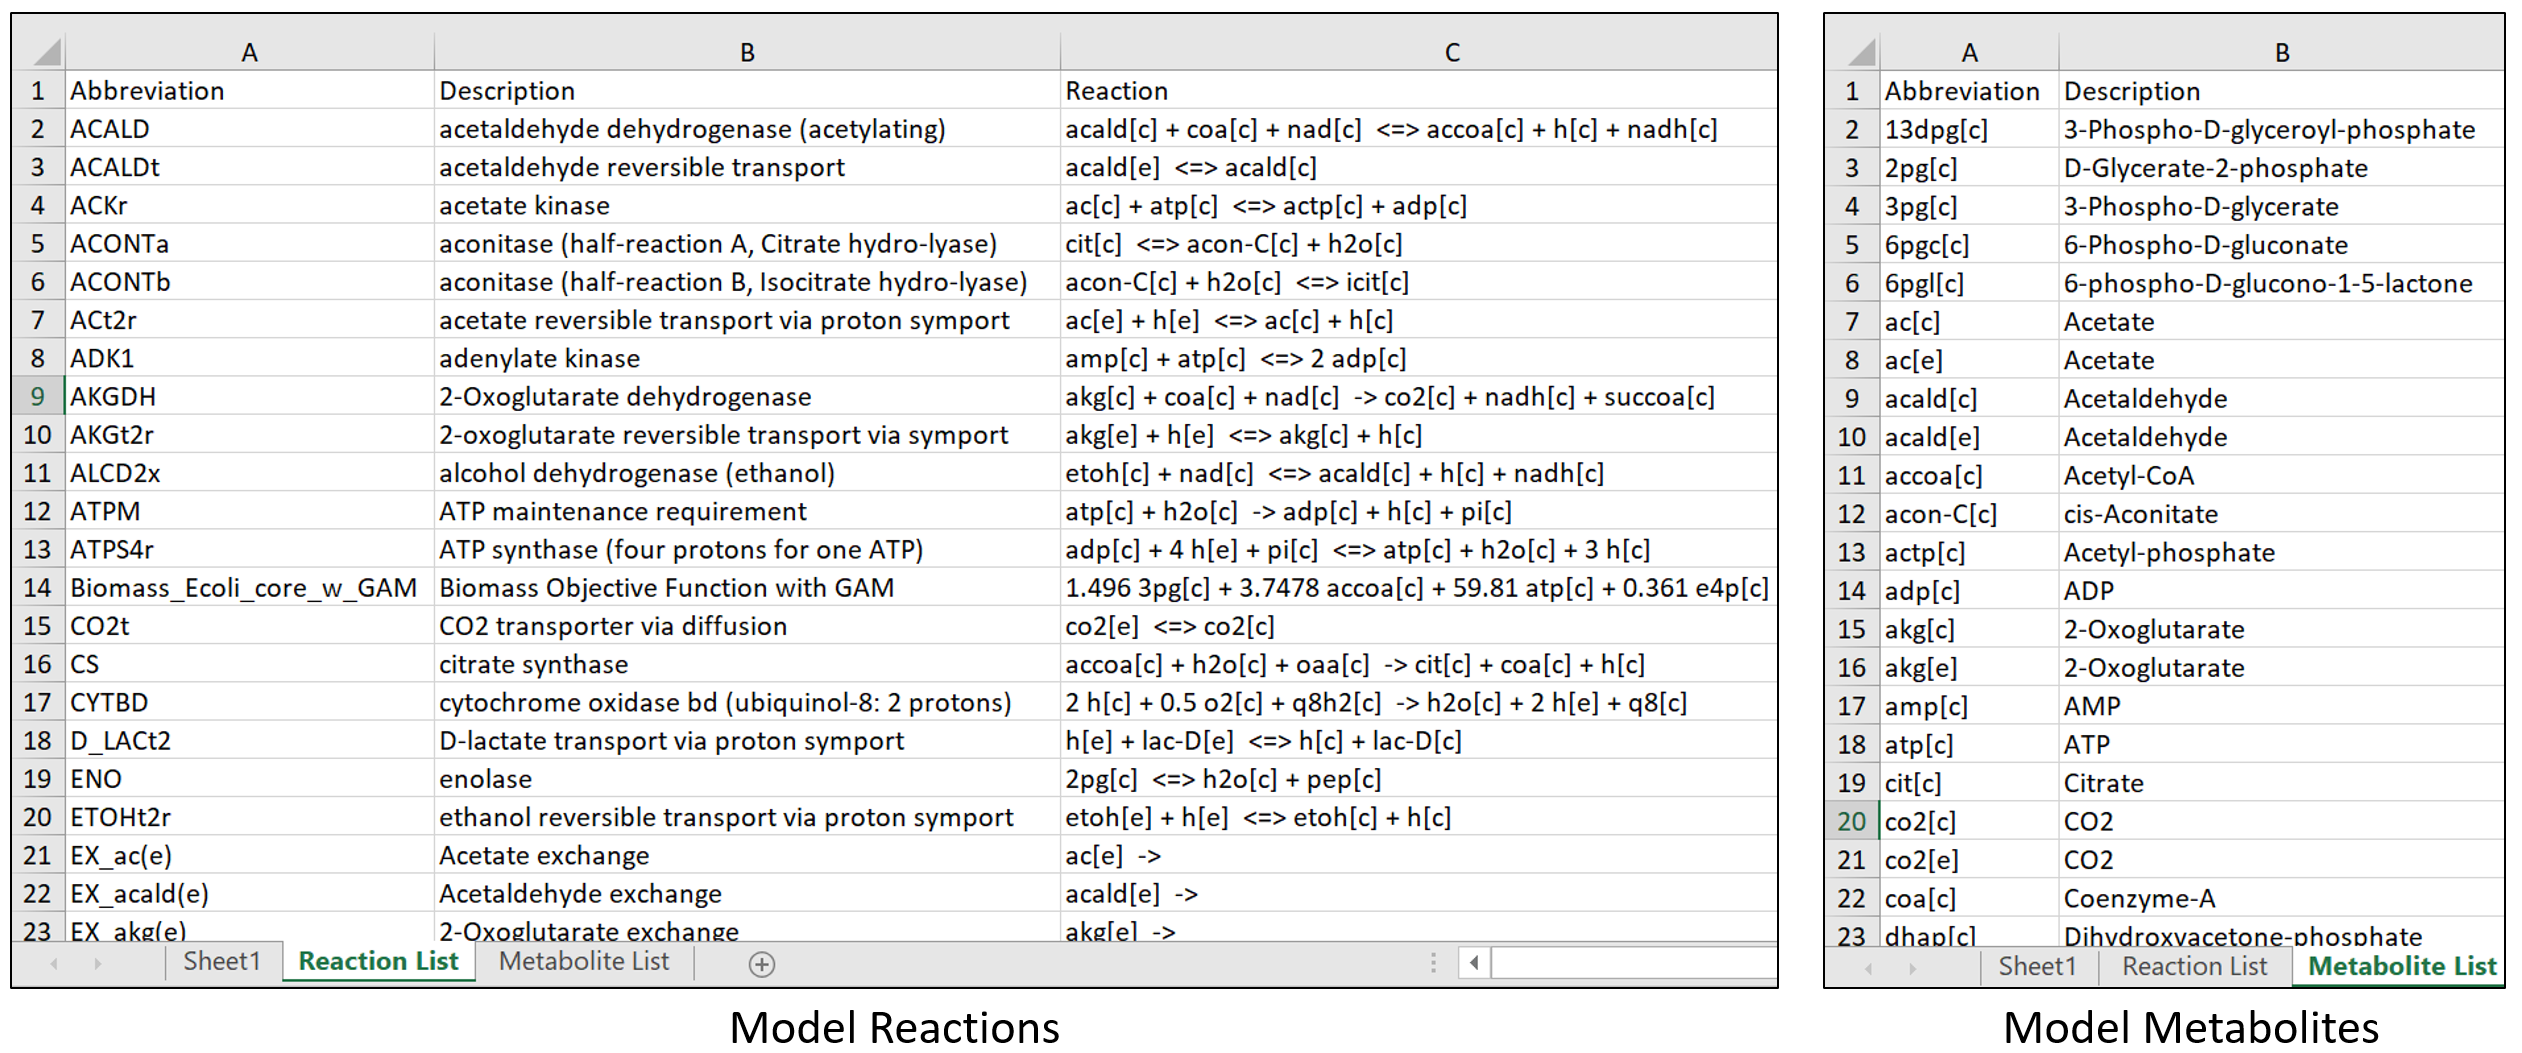

**Figura 4. **Captura de pantalla de "core_model.xls" que muestra una parte de la hoja de cálculo con reacciones y metabolitos del modelo.

Una forma de entender cómo funciona la célula es visualizar el funcionamiento de la célula a través de un mapa metabólico. Hay mapas disponibles en la instalación de la COBRA Toolbox para varios organismos diferentes que se pueden usar para visualizar los modelos y también superponer valores de flujo calculados en el mapa (discutiremos esto en la sección de análisis de balance de flujo). Para crear un mapa se requiere un archivo especial denominado "mapa de exportación". Para el caso del modelo central de *E.coli*, el mapa de exportación se denomina "ecoli_core_map.txt" y se incluye con la instalación predeterminada de la COBRA Toolbox. Los siguientes pasos se pueden usar para crear un mapa del núcleo de *E.coli* en un archivo "SVG" llamado "target.svg". Este archivo de mapa debe estar ubicado en su directorio de trabajo. *[Tiempo: segundos]*

map=readCbMap('ecoli_core_map.txt');
options.zeroFluxWidth = 0.1;
options.rxnDirMultiplier = 100;
drawCbMap(map);

La Figura 5 es una captura de pantalla del mapa central de* E.coli* producido por "drawflux".

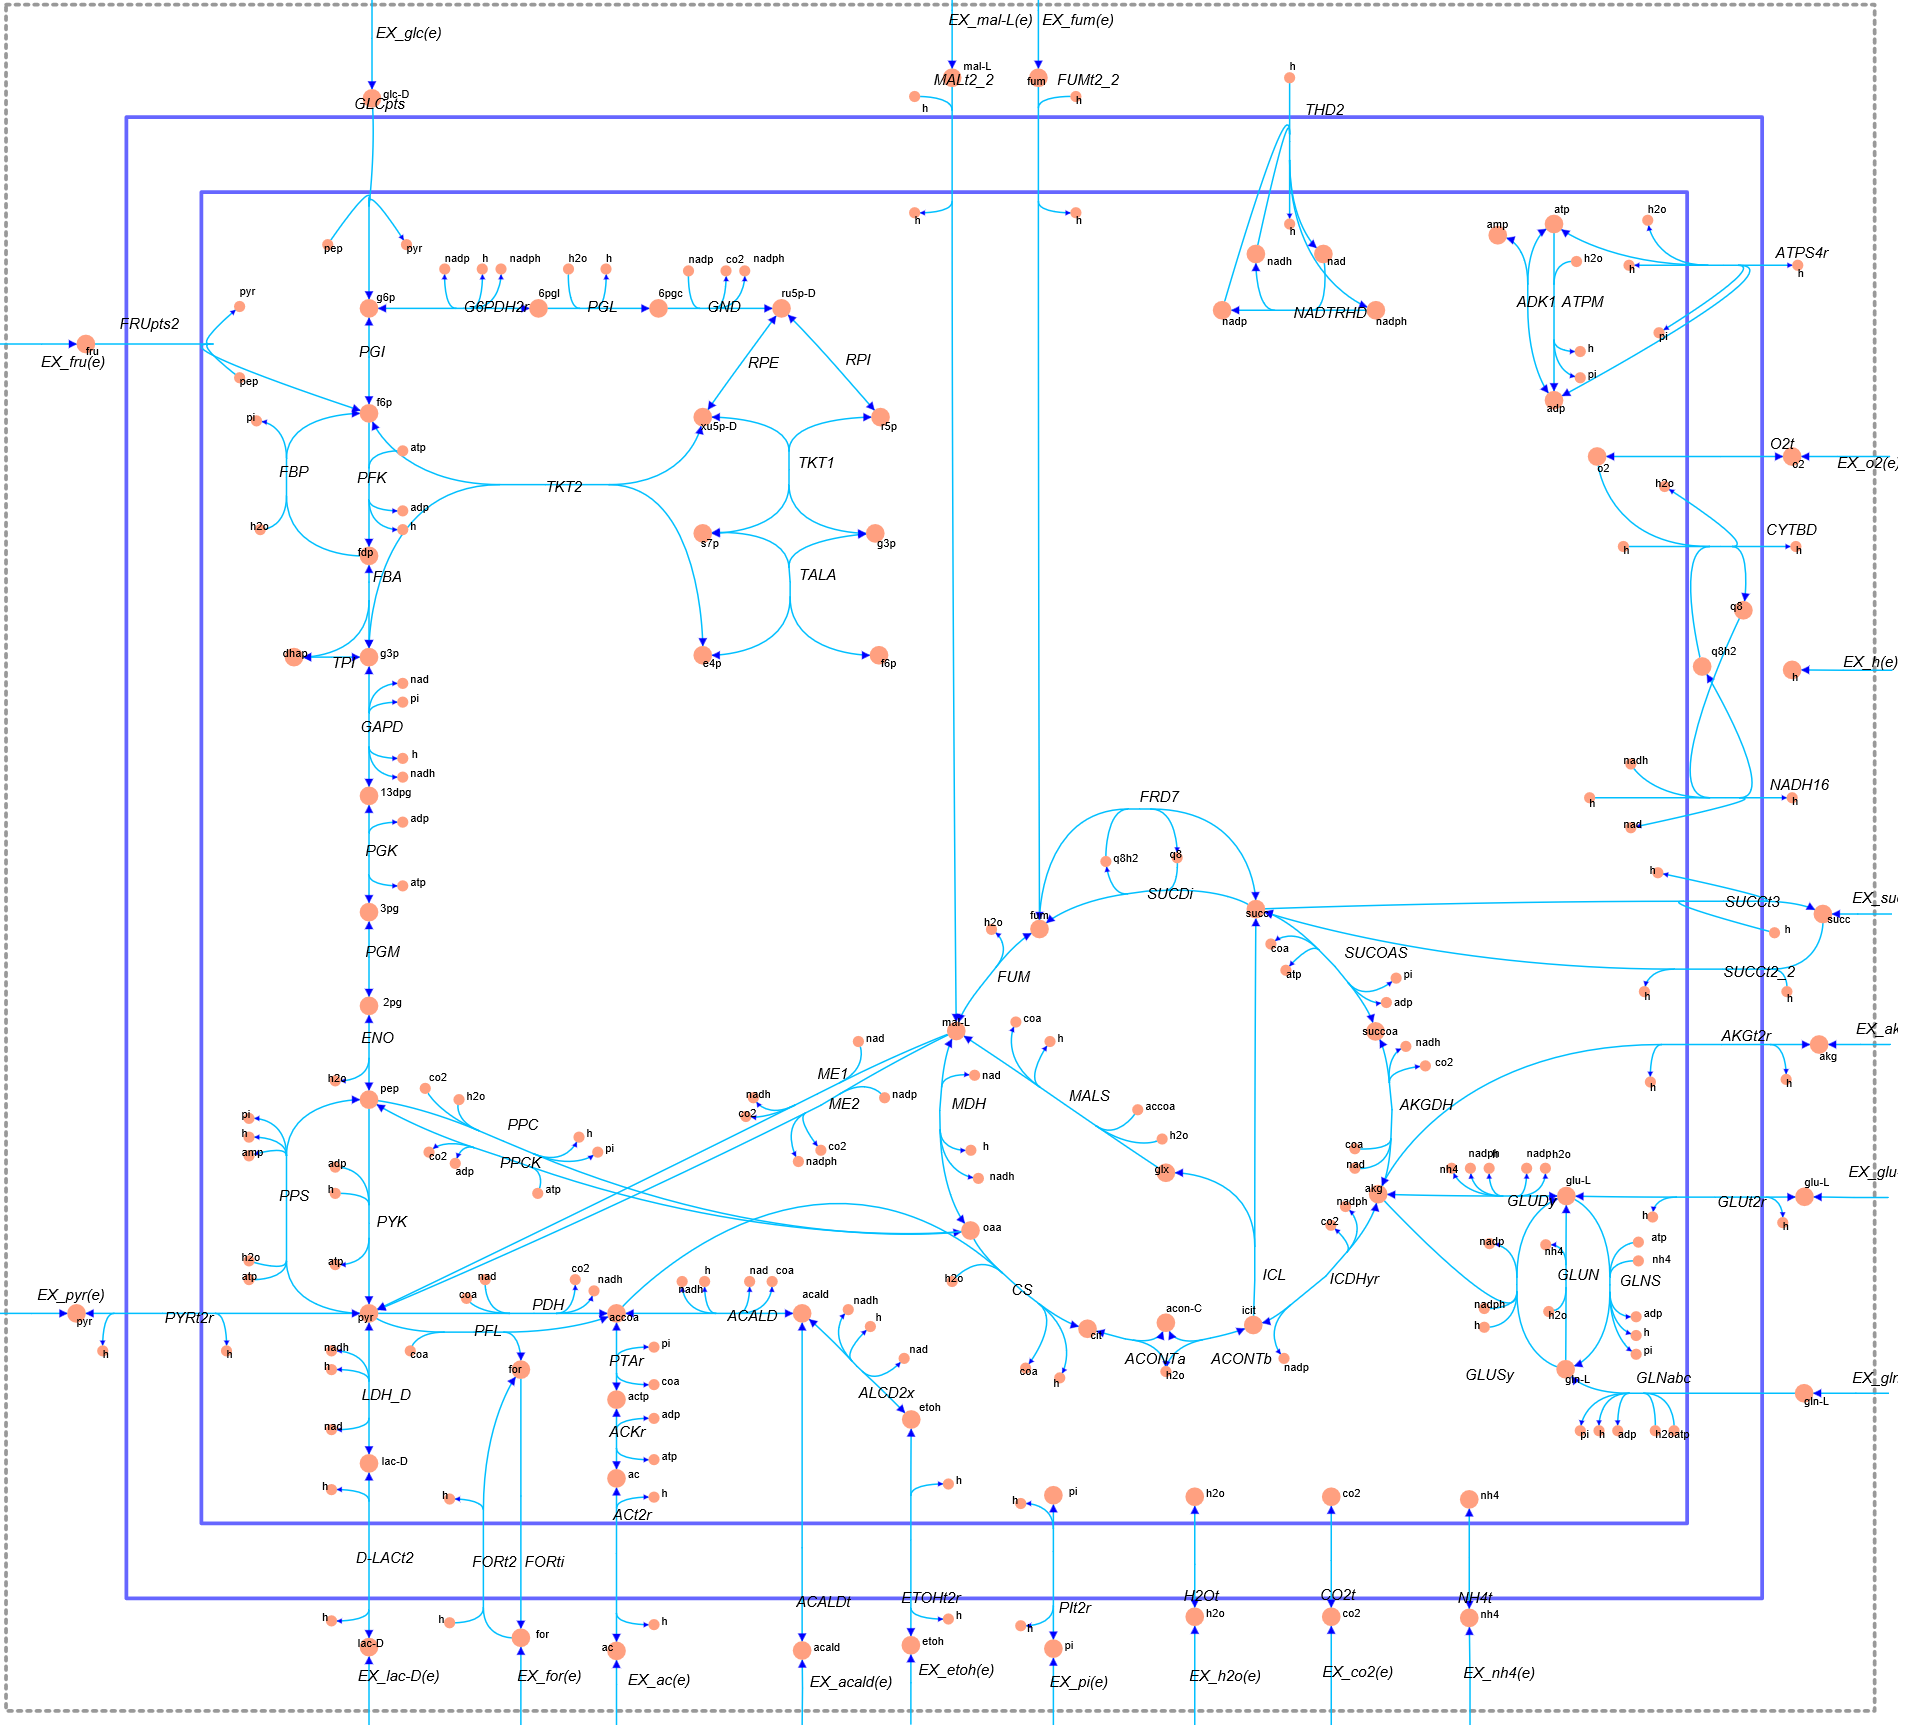

**Figure 5.** Captura de pantalla del mapa del modelo central de E.coli producido por "drawflux".

Este mapa SVG se puede leer con la mayoría de los navegadores y es muy fácil de usar para buscar y explorar la red *E.coli*.

### **2.A. Genes** 

Ahora, comencemos explorando algunas de las funciones del código Matlab y de la COBRA Toolbox que se pueden usar para extraer información sobre los genes del modelo. A continuación se muestra una colección de funciones de COBRA Toolbox que recuperan información clave de los genes en el modelo. Los genes solo están representados por su número de locus de gen (por ejemplo, b2097). El nombre del gen se puede obtener con una búsqueda rápida en el sitio web de EcoCyc ([https://www.ecocyc.org/](https://www.ecocyc.org/)). Para empezar, los genes incluidos en el modelo y sus geneID se almacenan en la estructura "model.genes". La función COBRA Toolbox "findGeneIDs" se puede utilizar para extraer el geneID de la estructura del modelo. Los primeros 10 genes del modelo y sus ID de genes se pueden imprimir de la siguiente manera. *[Tiempo: segundos]*

genes = cellstr(model.genes(1:10));
geneIDs = findGeneIDs(model, model.genes(1:10));
printLabeledData(model.genes(1:10),geneIDs)

Para el caso de encontrar un ID de gen único del modelo, el número de locus del gen debe incluirse entre comillas simples, como 'b_number'. *[Tiempo: segundos]*

findGeneIDs(model, 'b0116')

Ahora, para encontrar las reacciones asociadas con un gen dado, puede usar la función "`findRxnsFromGenes`" como se muestra a continuación. *[Tiempo: segundos]*

[results ListResults] = findRxnsFromGenes(model,'b0116', 0, 1)

Este resultado muestra que el gen "b0116" está asociado con las dos reacciones `AKGDH` y `PDH`.

### **2.B. Reacciones**

Las reacciones y sus rxnID se almacenan en la estructura "model.rxns" y los nombres de las reacciones se almacenan en "`model.rxnNames`". La función de COBRA Toolbox "`findRxnIDs`" se puede utilizar para extraer el rxnID de la estructura del modelo. Tenga en cuenta que la función de biomasa "`Biomass_Ecoli_core_w_GAM`" aparece como una de las reacciones. *[Tiempo: segundos]*

rxnIDs = findRxnIDs(model, model.rxns(1:15));
printLabeledData(model.rxns(1:15),rxnIDs)

Para encontrar un solo rxnID del modelo, use "findRxnIDs" con la abreviatura de reacción deseada incluida entre comillas simples, p. '`ENO`'. *[Tiempo: segundos]*

rxnIDs = findRxnIDs(model, 'ENO')

Encontrar el nombre de la reacción 'ENO' se puede recuperar usando la estructura "model.rxnNames" con la reacción deseada rxnID. *[Tiempo: segundos]*

model.rxnNames(rxnIDs)

Para encontrar la fórmula de la reacción, use la función "`printRxnFormula`". *[Tiempo: segundos]*

printRxnFormula(model,'ENO');

Para encontrar los genes asociados con una reacción determinada, puede utilizar la función "`findGenesRxns`". *[Tiempo: segundos]*

[geneList]=findGenesFromRxns(model,'ENO');
geneList{1:1}

Finalmente, hay momentos en los que es necesario encontrar todos los metabolitos "reactivos" que alimentan una reacción, así como todos los metabolitos "producto" que se producen en la reacción. Esto se puede lograr usando la función "`surfNet`" como se muestra a continuación (hay un tutorial COBRA sobre esto de Siu Hung Joshua Chan llamado "Browse Networks in the Matlab Command Window Using surfNet"). El resultado de esta función incluye una lista de los reactivos y productos basados en las fórmulas de reacción. Cabe señalar que en situaciones en las que una reacción se vuelve reversible, un metabolito que es un reactivo puede convertirse en un producto y un metabolito que es un producto puede convertirse en un reactivo. *[Tiempo: segundos]*

surfNet(model, 'GAPD')

En este caso, los metabolitos "reactivos" para la reacción GAPD son `g3p[c]`, `nad[c]` y `pi[c]` mientras que los metabolitos "producto" son `13dpg[c]`, `h[c]` y `nadh[c`] .

### **2.C. Metabolitos**

Los metabolitos incluidos en el modelo y sus ID de metabolitos (metID) se almacenan en la estructura "`model.mets`" y los nombres de los metabolitos se almacenan en `model.metNames`. La función de COBRA Toolbox "`findMetIDs`" se puede utilizar para extraer los metID de la estructura del modelo, como se muestra en el siguiente ejemplo. *[Tiempo: segundos]*

metIDs = findMetIDs(model, model.mets(1:15));
printLabeledData(model.mets(1:15),metIDs)

Para encontrar un solo metID del modelo, use "`findMetIDs`" con la abreviatura del metabolito deseado incluida entre comillas simples, p. '`akg[c]`'. *[Tiempo: segundos]*

metIDs = findMetIDs(model, 'akg[c]')

Encontrar el nombre de la reacción '`akg[c]`' produce *[Tiempo: segundos]*

model.metNames(metIDs)

Para encontrar la fórmula química del metabolito, puede usar la estructura "`model.metFormulas`" con un metID. *[Tiempo: segundos]*

model.metFormulas(metIDs)

Finalmente, para encontrar reacciones que produzcan y consuman un metabolito deseado, puede volver a utilizar la función "`surfNet`". Esto incluye una lista de las reacciones de consumo y producción basadas en las fórmulas de reacción. En algunas situaciones, si una reacción es reversible, las reacciones de producción/consumo podrían intercambiarse. *[Tiempo: segundos]*

surfNet(model, 'atp[c]')

Como era de esperar, debería haber una gran cantidad de consumidores de `atp[c]` pero solo una pequeña cantidad de productores.

### **2.D. Gene-Protein-Reaction Associations**

Una asociación gen-proteína-reacción (GPRA) muestra la relación booleana entre los genes que se requieren para producir una reacción específica (consulte la Figura 2). La relación booleana entre los genes y una reacción dada se puede encontrar utilizando la estructura "`model.grRules`" del modelo. Esto se muestra a continuación. *[Tiempo: segundos]*

rxnIDs = findRxnIDs(model, 'PYK');
model.grRules(rxnIDs)

Aquí hay un ejemplo de una relación gen-reacción más complicada. *[Tiempo: segundos]*

rxnIDs = findRxnIDs(model, 'ATPS4r');
model.grRules(rxnIDs)

### **2.E. **Restricciones del modelo

En las simulaciones basadas en restricciones, las restricciones del sistema se implementan de dos maneras en los modelos COBRA: 

- Como fórmulas de reacción que equilibran los metabolitos de entrada y salida de la reacción (balance de masa).

- Como desigualdades que imponen límites superior e inferior en las tasas de flujo de cada reacción en el modelo. 

Para establecer estas restricciones, a cada reacción se le asignan límites superior e inferior, que definen los flujos máximos y mínimos permitidos a través de las reacciones.

Para encontrar las restricciones para todas las reacciones en el modelo, COBRA Toolbox proporciona la función "`printConstraints(model,lb, ub)`" donde el valor "`lb`" es el límite inferior del flujo potencial de las reacciones mientras que "`ub`" se refiere al límite superior del flujo de reacciones. Es importante comprender la configuración de restricción predeterminada para el modelo central de *E.coli*. En este modelo, todas las reacciones reversibles en el citoplasma se establecen inicialmente de modo que su límite inferior sea -1000 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$ con un límite superior de +1000 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$. Por otro lado, las reacciones irreversibles, excepto ATPM, se establecen con un límite inferior de 0 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$ y un límite superior de +1000 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$. La reacción de mantenimiento de ATP (ATPM) se establece con un límite inferior de 0 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$ y un límite superior de +8,39 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$ (esto se discutirá más adelante). Todas las reacciones de intercambio, excepto EX_glc(e), están configuradas para permitir la secreción pero no la absorción, por lo tanto, un límite inferior de 0 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$ y un límite superior de +1000 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$. Para evitar confusiones, debe entenderse que todas las reacciones de intercambio, que son reacciones que interactúan entre el espacio extracelular y el citoplasmático, suponen que la secreción es positiva mientras que la captación se etiqueta como negativa. Finalmente, la reacción de intercambio de glucosa, EX_glc(e), se establece con un límite inferior de -10 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$ y un límite superior de +1000 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$.

Para ver las restricciones de las reacciones que no se establecen en los valores mínimo/máximo (-100\100), se pueden ajustar "`lb`" y "`ub`". *[Tiempo: segundos]*

% printConstraints(model,-100, +100)
% Para arreglar este bug, hagan clik izquierdo en printConstraints y
% seleccionen 'open "printConstraints"'. 
% Remplasen la linea 70 de la funcion por:
% boolRemainder = rxnSelection & ~(closedRxnBool | reversibleRxnBool | fwdRxnBool0b | revRxnBool0b | fwdRxnBoolNon0b | revRxnBoolNon0b);

Tenga en cuenta que la reacción de intercambio que controla la absorción de glucosa, '`EX_glc(e)` se establece automáticamente en -10 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$. 

Los resultados de los límites superior o inferior para una reacción en particular se pueden encontrar usando la estructura del modelo COBRA, "`model.lb`" para el límite inferior y "`model.ub`" para el límite superior. *[Tiempo: segundos]*

rxnIDs = findRxnIDs(model,'EX_glc(e)');
model.lb(rxnIDs)
model.ub(rxnIDs)

La modificación de las restricciones de una reacción se puede lograr con la función "`model = changeRxnBounds(model,rxnNameList,value,boundType)`". Para esta función, el segundo parámetro son las reacciones que deben restringirse, el tercer parámetro es la velocidad de flujo deseada y el cuarto parámetro puede ser '`u`': límite superior, '`l`': límite inferior o ' `b`' - ambos (Predeterminado = '`b`'). *[Tiempo: segundos]*

model = changeRxnBounds(model,'EX_glc(e)',-5,'l');
% printConstraints(model,-100, +100); % Mostrando el resultado del cambio.

Ahora puede ver que el límite inferior de la glucosa se ha cambiado a -5 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$ .

### **2.F. Funcion objetivo**

Para realizar análisis de balance de flujo es necesario definir un objetivo biológico o función objetivo. Para el caso de la predicción del crecimiento, el objetivo biológico es la producción de biomasa o la velocidad a la que los compuestos metabólicos se convierten en constituyentes de la biomasa. Esta producción de biomasa se representa matemáticamente mediante la adición al modelo de una "reacción de biomasa" artificial (`Biomass_Ecoli_core_w_GAM`) que consume metabolitos precursores en estequiometrías que simulan la producción de biomasa. Los precursores del modelo central de *E.coli* se muestran en la Figura 6.

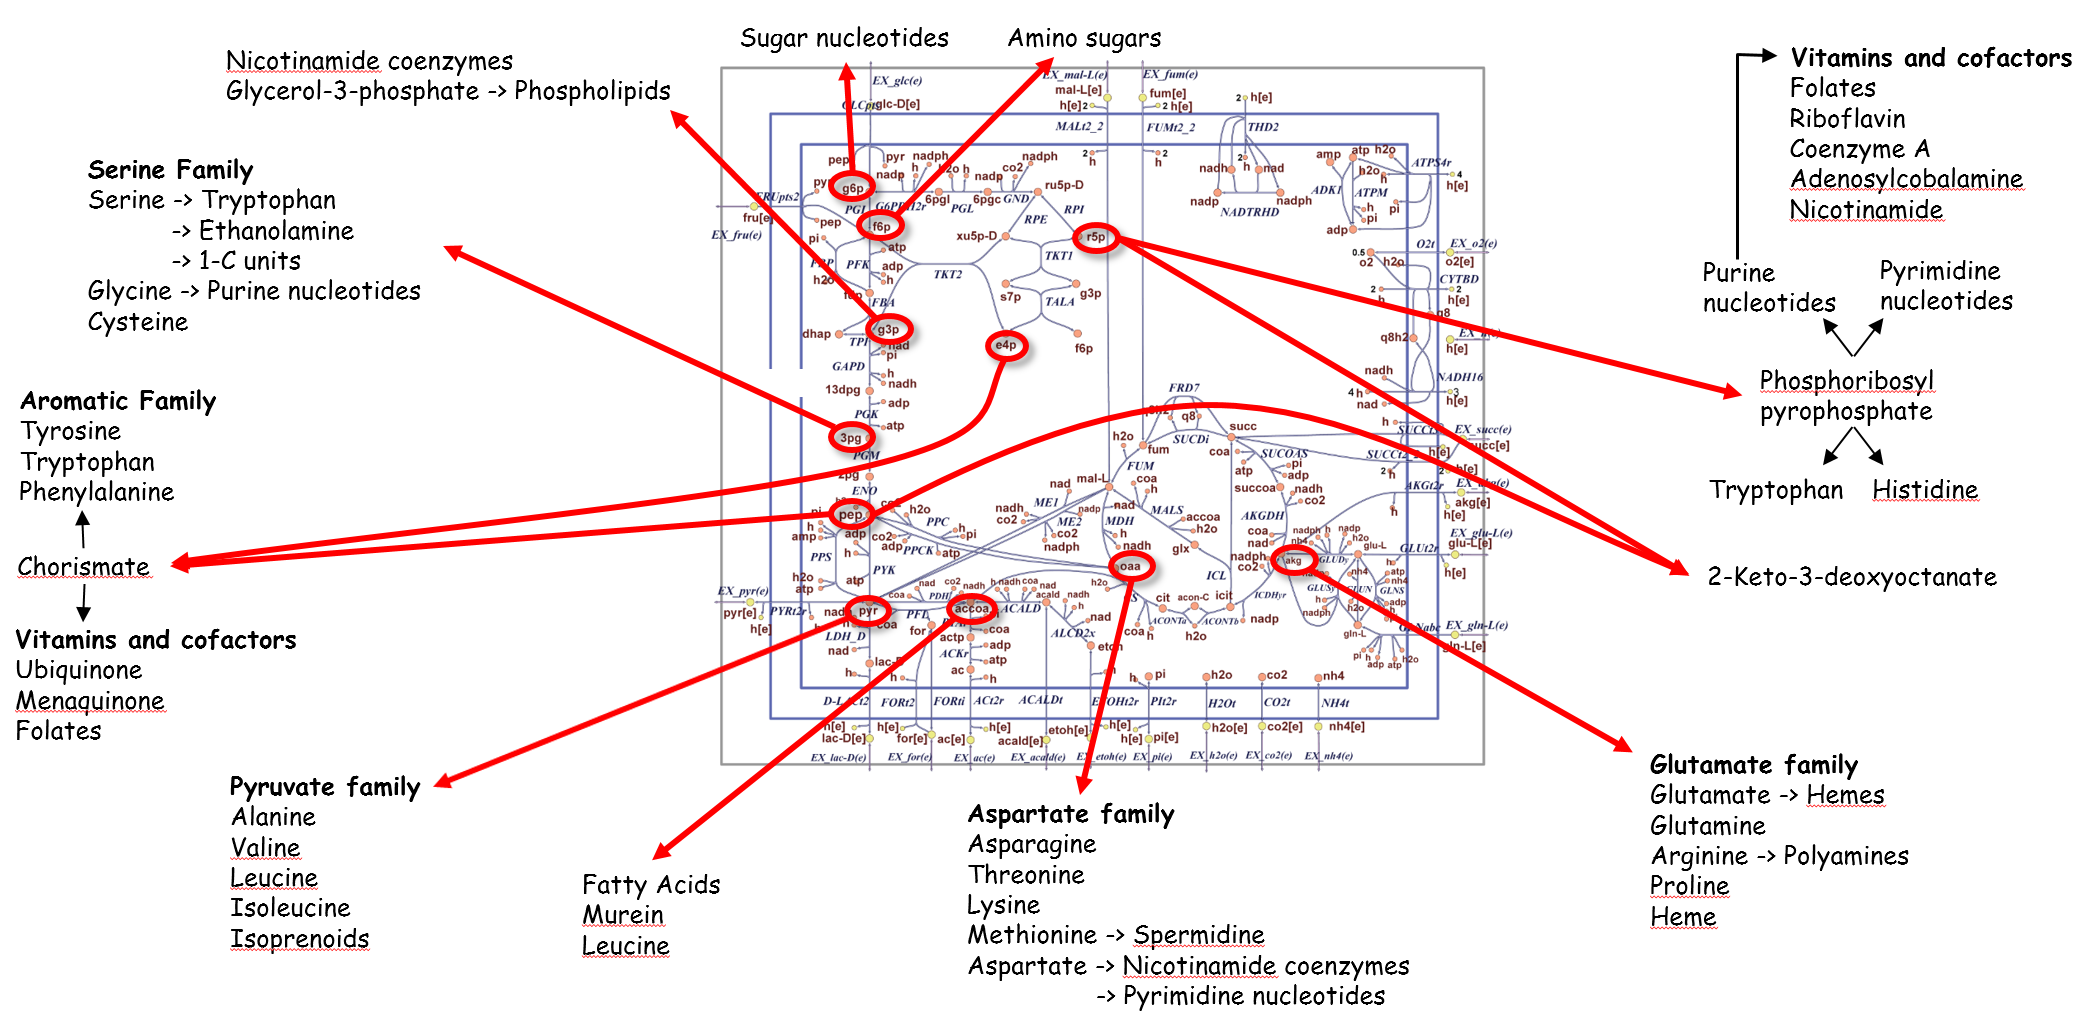

**                                                                                                                Figura 6.** Precursores del modelo central de *E.coli* [11].

La reacción de la biomasa también incluye cofactores clave (`atp[c]`, `adp[c]`, `nad[c]`, `nadh[c]`, `nadph[c]` y `pi[c]`) que son necesarios para el crecimiento y funcionamiento celular. La reacción de la biomasa se basa en mediciones experimentales de los componentes de la biomasa, lo que permite escalar la reacción para que su flujo sea igual a la tasa de crecimiento exponencial (μ) del organismo. Con la biomasa ahora representada en el modelo, la tasa máxima de crecimiento se puede predecir calculando las condiciones que maximizan el flujo a través de la reacción de la biomasa.

La reacción de biomasa y los metabolitos precursores ponderados se pueden inspeccionar imprimiendo la fórmula para la función de biomasa utilizando la función COBRA Toolbox "`printRxnFormula`". *[Tiempo: segundos]*

printRxnFormula(model,'Biomass_Ecoli_core_w_GAM')

La función objetivo también se puede verificar usando la función "`checkObjective(model)`" que imprimirá los coeficientes estequiométricos para cada metabolito junto con el nombre del objetivo. *[Tiempo: segundos]*

checkObjective(model)

La función objetivo para el modelo central de *E.coli* se configura automáticamente para que sea la reacción de la biomasa. También se puede configurar la función de biomasa para que sea la función objetivo usando model = changeObjective(model,'reaction name'') como se muestra a continuación. *[Tiempo: segundos]*

model = changeObjective(model,'Biomass_Ecoli_core_w_GAM');

### Peguntas

 1.- Que genes están asociados con la reacción '`succinate dehydrogenase (irreversible)'`?

2.- Que metabolitos pertenecen a esa reacción?

3.- Cual es el gen que se asocia con más reacciones?

4.- Cual es la reacción con más metabolitos?

5.- Cuales son los precursores de esos metabolitos?

6.- Cuales son los 4 metabolitos que participan en más reacciones?

7.- Cuales crees que son confactores mas importantes en el modelo *E.coli*?

8.- Cual es la unidad de flujo de una reacción? (Pista: 2.E. Restricciones del modelo)